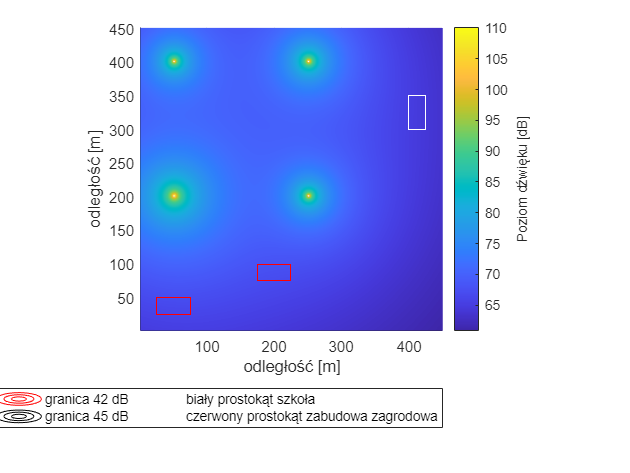

clearvars
a=450; %rozmiar naszej 'mapy'
b=450; %rozmiar naszej 'mapy'
LptD=38; %tło akustyczne
[x,y]=meshgrid(0:a, 0:b); %tworzymy siatkę w naszym przypadku jest to siatka 450 x 450, wraz ze skokiem o jeden metr
r_Z1=sqrt((x-50).^2+(y-400).^2); %ustalamy pozycję dla źródeł
r_Z2=sqrt((x-50).^2+(y-200).^2);
r_Z3=sqrt((x-250).^2+(y-200).^2);
r_Z4=sqrt((x-250).^2+(y-400).^2);


%wzór na poziom ciśnienia akustycznego dla źródeł monopolowych Lp = Lw(moc akustyczna źródła)-10log(4*pi*r^2)(odległość od źródła)
Lp_Z1=116-10*log10(4*pi*r_Z1.^2); % dzien 101 noc 83
Lp_Z2=121-10*log10(4*pi*r_Z2.^2); % dzien 105 noc 95
Lp_Z3=116-10*log10(4*pi*r_Z3.^2); % dzien 99 noc 81
Lp_Z4=117-10*log10(4*pi*r_Z4.^2); % dzien 99 noc 85

Lp_Z1=10*log10(10.^(0.1*Lp_Z1)+10.^(0.1*LptD)); %tutaj uwzględniamy wpływ tła akustycznego 
Lp_Z2=10*log10(10.^(0.1*Lp_Z2)+10.^(0.1*LptD));
Lp_Z3=10*log10(10.^(0.1*Lp_Z3)+10.^(0.1*LptD));
Lp_Z4=10*log10(10.^(0.1*Lp_Z4)+10.^(0.1*LptD));

L=10*log10(10.^(0.1*Lp_Z1)+10.^(0.1*Lp_Z2)+10.^(0.1*Lp_Z3)+10.^(0.1*Lp_Z4)); %suma ciśnień akustycznych w danym punktach    
surf(L, EdgeColor="none")
view([0 90])
% xlim([0 450])
% ylim([-150 300])
axis equal
hold on
[~,c]=contour(L,[0,42], LineColor='red'); %rysuje kontury do wartości max 42 [dB] - czerowna linia
[~,c1]=contour(L,[0,45], LineColor='black'); %rysuje kontury do wartości max 45 [dB] - czarna linia
c.ZLocation='zmax';
c1.ZLocation='zmax';
    
hold on
colorbar%
legend('','granica 65 dB','granica 70 dB','Location','southoutside','NumColumns',2)
%szkoła
plot3(400, 300:1:350,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','white',...
    'MarkerFaceColor',[1 .6 .6]);
plot3(425, 300:1:350,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','white',...
    'MarkerFaceColor',[1 .6 .6])
plot3(400:425, 300,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','white',...
    'MarkerFaceColor',[1 .6 .6])
plot3(400:425, 350,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','white',...
    'MarkerFaceColor',[1 .6 .6])


%zabudowa zagrodowa 1
plot3(25:75, 50,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])
plot3(25:75, 25,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])
plot3(25, 25:50,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])
plot3(75, 25:50,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])

%zabudowa zagrodowa 2
plot3(175:225, 100,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])
plot3(175:225, 75,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])
plot3(175, 75:100,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])
plot3(225, 75:100,150, 'square', 'MarkerSize',0.5,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor',[1 .6 .6])
hold off
clr=colorbar;
clr.Label.String ="Poziom dźwięku [dB]";
xlabel("odległość [m]");
ylabel("odległość [m]");
legend('','granica 42 dB','granica 45 dB',['biały prostokąt ','szkoła'],['czerwony prostokąt ', 'zabudowa zagrodowa'],'Location','southoutside','NumColumns',2)


%L1 = array2table(L);
%writetable(L1,'noc_zredukowane.xlsx') %zapisujemy plik

Lp_Z1(45,75)  %szkoła (325,400) Z1(45,75) Z2(80,200)

ans = 54.0141

Lp_Z2(45,75)

ans = 66.0472

Lp_Z3(45,75)

ans = 57.6036

Lp_Z4(45,75)

ans = 54.0832

L(45,75)

ans = 67.0830